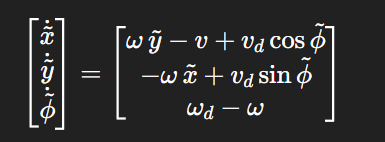

proof

%% Symbolic proof of Kanayama error dynamics
clear; clc;
syms t real

% States (functions of time)
syms x(t)  y(t)  phi(t)
syms xd(t) yd(t) phid(t)

% Inputs / velocities (functions of time)
syms v(t) vd(t) w(t) wd(t)

%% 1) Define position errors in world frame
ex  = xd(t) - x(t);
ey  = yd(t) - y(t);
ephi = phid(t) - phi(t);

%% 2) Kanayama (body-frame) errors (Eq. 14)
xt =  cos(phi(t))*ex + sin(phi(t))*ey;   % \tilde x
yt = -sin(phi(t))*ex + cos(phi(t))*ey;   % \tilde y
phit = ephi;                       % \tilde phi

E   = [xt; yt; phit];              % error vector

%% 3) Compute time derivative d/dt(Eq. 14) -> LHS
dE_dt = diff(E, t);    % this is \dot{\tilde x}, \dot{\tilde y}, \dot{\tilde \phi}
dxt = simplify(dE_dt(1));
dyt = simplify(dE_dt(2));
dphit = simplify(dE_dt(3));

%% 4) Substitute unicycle kinematics
% Robot:
%   xdot  = v cos(phi)
%   ydot  = v sin(phi)
%   phidot = w
% Desired:
%   xddot = vd cos(phid)
%   yddot = vd sin(phid)
%   phiddot = wd
dxt = subs(dxt,  [diff(x,t),     diff(y,t),     diff(xd,t),        diff(yd,t),        diff(phi,t), diff(phid,t)], ...
                 [v*cos(phi),    v*sin(phi),    vd*cos(phid),      vd*sin(phid),      w,           wd]);
dyt = subs(dyt,  [diff(x,t),     diff(y,t),     diff(xd,t),        diff(yd,t),        diff(phi,t), diff(phid,t)], ...
                 [v*cos(phi),    v*sin(phi),    vd*cos(phid),      vd*sin(phid),      w,           wd]);
dphit = subs(dphit, [diff(phi,t), diff(phid,t)], [w, wd]);

dxt = simplify(dxt);
dyt = simplify(dyt);
dphit = simplify(dphit);

%% 5) Build LHS vector (from differentiating Eq. 14)
LHS = [dxt; dyt; dphit];
LHS

$$LHS = \begin{array}{l} \left(\begin{array}{c} \mathrm{vd}\left(t\right)\,\cos\left(\sigma_{1}\right)-v\left(t\right)-\cos\left(\varphi \left(t\right)\right)\,w\left(t\right)\,y\left(t\right)+\cos\left(\varphi \left(t\right)\right)\,w\left(t\right)\,\mathrm{yd}\left(t\right)+\sin\left(\varphi \left(t\right)\right)\,w\left(t\right)\,x\left(t\right)-\sin\left(\varphi \left(t\right)\right)\,w\left(t\right)\,\mathrm{xd}\left(t\right)\\ \cos\left(\varphi \left(t\right)\right)\,w\left(t\right)\,x\left(t\right)-\mathrm{vd}\left(t\right)\,\sin\left(\sigma_{1}\right)-\cos\left(\varphi \left(t\right)\right)\,w\left(t\right)\,\mathrm{xd}\left(t\right)+\sin\left(\varphi \left(t\right)\right)\,w\left(t\right)\,y\left(t\right)-\sin\left(\varphi \left(t\right)\right)\,w\left(t\right)\,\mathrm{yd}\left(t\right)\\ \mathrm{wd}\left(t\right)-w\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\varphi \left(t\right)-\mathrm{phid}\left(t\right) \end{array}$$

%% 6) Build RHS from Eq. 15, expressed in tilde variables
% RHS:
%   \dot{\tilde x} = w*tilde_y - v + vd*cos(tilde_phi)
%   \dot{\tilde y} = -w*tilde_x + vd*sin(tilde_phi)
%   \dot{\tilde\phi} = wd - w
RHS = [ w(t)*yt - v(t) + vd(t)*cos(phit);
       -w(t)*xt + vd(t)*sin(phit);
        wd(t) - w(t)];

%% 7) Check equality LHS == RHS symbolically
% (simplify the difference; if it's [0;0;0], the equations match)
diff_vec = simplify(LHS - RHS);

disp('LHS (from d/dt of Eq. 14):');

LHS (from d/dt of Eq. 14):


pretty(LHS)

/ vd(t) cos(#1) - v(t) - cos(φ(t)) w(t) y(t) + cos(φ(t)) w(t) yd(t) + sin(φ(t)) w(t) x(t) - sin(φ(t)) w(t) xd(t) \
|                                                                                                                |
|     cos(φ(t)) w(t) x(t) - vd(t) sin(#1) - cos(φ(t)) w(t) xd(t) + sin(φ(t)) w(t) y(t) - sin(φ(t)) w(t) yd(t)    |
|                                                                                                                |
\                                                  wd(t) - w(t)                                                  /

where

   #1 == φ(t) - phid(t)




disp('RHS (Eq. 15 substituted):');

RHS (Eq. 15 substituted):


pretty(RHS)

/ vd(t) cos(#1) - v(t) - w(t) (cos(φ(t)) #2 - sin(φ(t)) #3) \
|                                                           |
|     w(t) (cos(φ(t)) #3 + sin(φ(t)) #2) - vd(t) sin(#1)    |
|                                                           |
\                        wd(t) - w(t)                       /

where

   #1 == φ(t) - phid(t)

   #2 == y(t) - yd(t)

   #3 == x(t) - xd(t)




disp('LHS - RHS (should be zero):');

LHS - RHS (should be zero):


pretty(diff_vec)

/ 0 \
|   |
| 0 |
|   |
\ 0 /

